# Campisi equation ( factor analysis for bonds)

## 0.Definition

Campisi model decomposes the alpha into 3 parts, which is Income returns, treasure returns and Credit return.

Firstly, income returns could be sub-decomposed into coupon returns and convergence return;

Secondly,treasure returns could be sub-decomposed into duration management returns and duration structure returns;

At last, credit returns could be sub-decomposed into bond portfolio returns and single bond holding returns.

### (1) Pricing the returns of the bond

The price of the bond is the discount of the cash flow, as following equation shows:


$$P=\sum_{n=1}^N \frac{C}{{\left(1+\frac{y}{k}\right)}^n }+\frac{F}{{\left(1+\frac{y}{k}\right)}^N }$$


where:

$P$: Market price of the bond;

$C$:Interest

$F$:Final value of the bond

$y$:yield to maturity

$k$:number of interest payment per year

$N$:total number of interest payment

practically, the trade often happens before the next interst payment day, therefore, the above equation could be adjusted as:


$$P=\frac{C}{{\left(1+\frac{y}{k}\right)}^{n+m} }+\sum_{n=1}^N \frac{C}{{\left(1+\frac{y}{k}\right)}^{n+m} }+\frac{F}{{\left(1+\frac{y}{k}\right)}^{N+m} }$$


where $m$ is the ratio of the remaining days over the total date witin two adjacent interest payment point.

### (2) Duration of the bond

The duration of the bond is the average weighted value of the payment time, defined as (or namely, the Macaulay Duration):


$$D=\frac{\frac{m}{k}*C}{{\left(1+\frac{y}{k}\right)}^m }+\sum_{n=1}^N \;\frac{\frac{m+n}{k}*C}{{\left(1+\frac{y}{k}\right)}^{m+n} }+\frac{\frac{m+N}{k}*F}{{\left(1+\frac{y}{k}\right)}^{N+m} }$$


An transformation of the D, is the modified duration "MD", defined as:


$$\mathrm{MD}=\frac{D}{1+\frac{y}{k}}$$


As mentioned above, the duration is a weighted time value, therefore, the duration of the bond portfolio is equal to the average weighted value of the MD, which is:


$${\mathrm{MD}}_p =\sum_{i=1}^N w_i *{\mathrm{MD}}_i$$


where:

$w_i$: the weight of the market value of the bond 'i' in the portfolio.

### (3) Differential equation of the bond price 'P'

Base on the equations above, the partial differntial equation is defined as:


$$\frac{\partial P}{\partial y}=$$

$$\frac{-\frac{m}{k}*C}{{\left(1+\frac{y}{k}\right)}^{m+1} }+\sum_{n=1}^N \;\frac{-\frac{m+n}{k}*C}{{\left(1+\frac{y}{k}\right)}^{m+n+1} }+\frac{-\frac{m+N}{k}*F}{{\left(1+\frac{y}{k}\right)}^{N+m+1} }$$



$$=-\frac{1}{1+\frac{y}{k}}\left\lbrack \frac{\frac{m}{k}*C}{{\left(1+\frac{y}{k}\right)}^m }*\frac{1}{P}+\sum_{n=1}^N \;\frac{\frac{m+n}{k}*C}{{\left(1+\frac{y}{k}\right)}^{m+n} }*\frac{1}{P}+\frac{\frac{m+N}{k}*F}{{\left(1+\frac{y}{k}\right)}^{N+m} }\right\rbrack$$



$$=-\frac{1}{1+\frac{y}{k}}*D*P$$



$$=-\mathrm{MD}*P$$


the above equation shows the bond price is inversely propertional to the yields. assume a bond with fixed price and big value of MD, 1BP change in yields will alter the price in the opposite direction.


$$\frac{\partial P}{\partial m}=$$

$$\frac{-C*\mathrm{ln}\left(1+\frac{y}{k}\right)}{{\left(1+\frac{y}{k}\right)}^m }+\sum_{n=1}^N \;\frac{-C*\mathrm{ln}\left(1+\frac{y}{k}\right)}{{\left(1+\frac{y}{k}\right)}^{m+n} }+\frac{-F*\mathrm{ln}\left(1+\frac{y}{k}\right)}{{\left(1+\frac{y}{k}\right)}^{N+m} }$$



$$=-\mathrm{ln}\left(1+\frac{y}{k}\right)\left\lbrack \frac{C}{{\left(1+\frac{y}{k}\right)}^{n+m} }+\sum_{n=1}^N \frac{C}{{\left(1+\frac{y}{k}\right)}^{n+m} }+\frac{F}{{\left(1+\frac{y}{k}\right)}^{N+m} }\right\rbrack$$



$$=-\mathrm{ln}\left(1+\frac{y}{k}\right)*P$$



$$\approx -\frac{y}{k}*P$$


base on the equation above, the differential of the price is defined as:


$$\mathrm{dP}=\frac{\partial P}{\partial y}*\mathrm{dy}+\frac{\partial P}{\partial t}*\mathrm{dt}$$



$$=-\mathrm{MD}*P*\mathrm{dy}+\left(-\frac{y}{k}*P*k*\mathrm{dm}\right)$$



$$=-\mathrm{MD}*P*\mathrm{dy}+\left(-y*P*\mathrm{dm}\right)$$


the returns of the bond could be represented by:


$$R=\frac{\mathrm{dP}}{P}=-\mathrm{MD}*\mathrm{dy}-y*\mathrm{dm}$$


considet the discrete form:


$$R=y*\Delta t-\mathrm{MD}*\Delta y$$


the first term of the equation$y*\Delta t$ is the returns of the bond, which named as Income returns, the income factor could be sub-decomposed into coupon returns$C*\Delta t$ and convergence return$\left(y-C\right)*\Delta t$;

the second term $-\mathrm{MD}*\Delta y$ is the returns from the change of yields to maturity, it could be sub-decomposed into tresure return$-\mathrm{MD}*\Delta y_{\mathrm{Tresure}}$ and credit returns$-\mathrm{MD}*\Delta y_{\mathrm{Credit}}$.

### (4) Return decomposition

According to the Brison model, the returns of the bond could be described as:


$$\sum_i w_{i,\;p} R_i =\sum_i w_{i,\;p} *y_i *\Delta t+\sum_i w_{i,\;p} \left(-\mathrm{MD}\right)*\Delta y_{\mathrm{Tresure},\;i} +\sum_i w_{i,\;p}$$

$$\left(-\mathrm{MD}\right)*\Delta y_{\mathrm{Credit},\;i}$$


The TR could be sub-decomposed into:


$$\begin{array}{l}
\sum_i w_{i,\;p} R_i -\sum_i W_{i,\;b} R_i \\
=\sum_i \left(w_{i,\;p} -W_{i,\;b} \right)*y_i *\Delta t+\sum_i \left(w_{i,\;p} -W_{i,\;b} \right)\left(-\mathrm{MD}\right)*\Delta y_{\mathrm{Tresure},\;i} +\sum_i \left(w_{i,\;p} -W_{i,\;b} \right)\left(-\mathrm{MD}\right)*\Delta y_{\mathrm{Credit},\;i} 
\end{array}$$


where Income returns is defined as:


$$\mathrm{IR}=\sum_i \left(w_{i,\;p} -W_{i,\;b} \right)*y_i *\Delta t$$


 the treasure returns in the above equation is defined as:


$$\sum_i \left(w_{i,\;p} -W_{i,\;b} \right)\left(-\mathrm{MD}\right)*\Delta y_{\mathrm{Tresure},\;i}$$


which could be sub-decompoed into


$$\sum_j w_{j,p} \left(-{\mathrm{MD}}_{j,p} \right)*\Delta y_{\mathrm{Tresure},\;j,\;P} -\sum_j w_{j,\;b} \left(-{\mathrm{MD}}_{j,\;b} \right)*\Delta y_{\mathrm{Tresure},\;j,\;b}$$


Duration management returns:


$$\mathrm{DMR}=\sum_j \left\lbrack w_{j,p} *\left(-{\mathrm{MD}}_{j,p} \right)-w_{j,\;b} *\left(-{\mathrm{MD}}_{j,\;b} \right)\right\rbrack *\Delta y_{\mathrm{Tresure},\;j,\;b}$$


Duration structure returns:


$$\mathrm{DSE}=\sum_j w_{j,\;b} *\left(-{\mathrm{MD}}_{j,b} \right)*\left(\Delta y_{\mathrm{Tresure},\;j,\;p} -\Delta y_{\mathrm{Tresure},\;j,\;b} \right)$$


Bond portfolio returns:


$$\mathrm{BPR}=\sum_k \left\lbrack w_{k,p} *\left(-{\mathrm{MD}}_{k,p} \right)-w_{k,b} *\left(-{\mathrm{MD}}_{k,\;b} \right)\right\rbrack *\Delta y_{\mathrm{credit},k,b} \;$$


Single bond holding returns:


$$\mathrm{SBHR}=\sum_k w_{k,b} *\left(-{\mathrm{MD}}_{k,b} \right)*\left(\Delta y_{\mathrm{credit},k,p} -\Delta y_{\mathrm{credit},k,b} \right)$$


Created in 2020-12-21 by XuSUN.

## 1.Initialization

% Close all the windows,clear the workspace and the command window
clc;
clear all;
close all;


## 2.Load / Create the data + Calculate the duration & modified duration

% Case 1: National debt
% Given a cash flow of 5 payments of 2410000 and a final payment 102410000, 
% with a periodic yield of 2.41%.
principal = 1e8;
y = 2.41/100;
k = 1;
m = k/k;
N = 4;
C = ones(1,N).*y.*principal;
C = [2410000, 2410000, 2410000, 2410000];
F = C(:,end) + principal;

% Calculate the price of the bond.
P = bondprice(C,F,y,k,m,N);

% Calculate the duration of the bond.
D = bondduration(P,C,F,y,k,m,N);

% Calculate the modified duration of the bond.
MD = modifiedduration(D,y,k);

format shortG;
fprintf('Price of the bond:    %.4f\n',P);

Price of the bond:    102139465.1267


fprintf('bond duration:    %.4f\n',D);

bond duration:    4.7750


fprintf('modified duration:    %.4f\n',MD);

modified duration:    4.6626


% Case 2: Corporate Bonds AAA
principal_CB3A = 1e7;
y_CB3A = 3/100;
k_CB3A = 1;
m_CB3A = k_CB3A/k_CB3A;
N_CB3A = 4;
C_CB3A = ones(1,N_CB3A).*y_CB3A.*principal_CB3A;
F_CB3A = C_CB3A(:,end) + principal_CB3A;

% Calculate the price of the Corporate Bonds AAA, named as "P_CB3A"
P_CB3A = bondprice(C_CB3A,F_CB3A,y_CB3A,k_CB3A,m_CB3A,N_CB3A);

% Calculate the duration of the Corporate Bonds AAA, named as "D_CB3A"
D_CB3A = bondduration(P_CB3A,C_CB3A,F_CB3A,y_CB3A,k_CB3A,m_CB3A,N_CB3A);

% Calculate the modified duration of the Corporate Bonds AAA, named as "MD_CB3A"
MD_CB3A = modifiedduration(D_CB3A,y_CB3A,k_CB3A);

format shortG;
fprintf('Price of the bond:    %.4f\n',P_CB3A);

Price of the bond:    10258782.6353


fprintf('bond duration:    %.4f\n',D_CB3A);

bond duration:    4.7242


fprintf('modified duration:    %.4f\n',MD_CB3A);

modified duration:    4.5866


% Case 3: Corporate Bonds AA+
principal_CB2APlus = 5e6;
y_CB2APlus = 4.5/100;
k_CB2APlus = 1;
m_CB2APlus = k_CB2APlus/k_CB2APlus;
N_CB2APlus = 4;
C_CB2APlus = ones(1,N_CB2APlus).*y_CB2APlus.*principal_CB2APlus;
F_CB2APlus = C_CB2APlus(:,end) + principal_CB2APlus;

% Calculate the price of the Corporate Bonds AA+, named as "P_CB2A"
P_CB2APlus = bondprice(C_CB2APlus,F_CB2APlus,y_CB2APlus,k_CB2APlus,m_CB2APlus,N_CB2APlus);

% Calculate the duration of the Corporate Bonds AA+, named as "D_CB2A"
D_CB2APlus = bondduration(P_CB2APlus,C_CB2APlus,F_CB2APlus,y_CB2APlus,k_CB2APlus,m_CB2APlus,N_CB2APlus);

% Calculate the modified duration of the Corporate Bonds AA+, named as "MD_CB2A"
MD_CB2APlus = modifiedduration(D_CB2APlus,y_CB2APlus,k_CB2APlus);

format shortG;
fprintf('Price of the bond:    %.4f\n',P_CB2APlus);

Price of the bond:    5180551.4855


fprintf('bond duration:    %.4f\n',D_CB2APlus);

bond duration:    4.6019


fprintf('modified duration:    %.4f\n',MD_CB2APlus);

modified duration:    4.4037


% Case 4: Corporate Bonds AA
principal_CB2A = 1e6;
y_CB2A = 5/100;
k_CB2A = 1;
m_CB2A = k_CB2A/k_CB2A;
N_CB2A = 4;
C_CB2A = ones(1,N_CB2A).*y_CB2A.*principal_CB2A;
F_CB2A = C_CB2A(:,end) + principal_CB2A;

% Calculate the price of the Corporate Bonds AA, named as "P_CB2A"
P_CB2A = bondprice(C_CB2A,F_CB2A,y_CB2A,k_CB2A,m_CB2A,N_CB2A);

% Calculate the duration of the Corporate Bonds AA, named as "D_CB2A"
D_CB2A = bondduration(P_CB2A,C_CB2A,F_CB2A,y_CB2A,k_CB2A,m_CB2A,N_CB2A);

% Calculate the modified duration of the Corporate Bonds AA, named as "MD_CB2A"
MD_CB2A = modifiedduration(D_CB2A,y_CB2A,k_CB2A);

format shortG;
fprintf('Price of the bond:    %.4f\n',P_CB2A);

Price of the bond:    1039176.3083


fprintf('bond duration:    %.4f\n',D_CB2A);

bond duration:    4.5631


fprintf('modifiedduration:    %.4f\n',MD_CB2A);

modifiedduration:    4.3458


## 3.Campisi model calculation

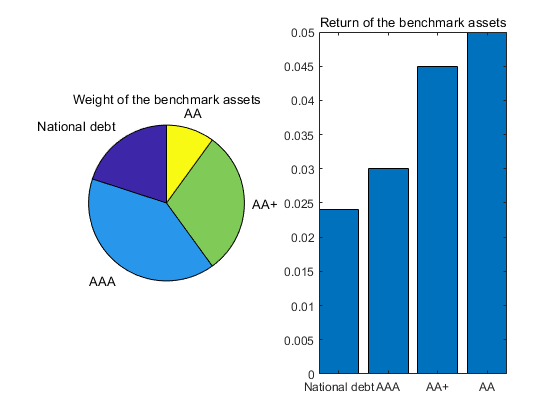

% Parameters of the bench mark assets
% [National debt, AAA, AA+, AA]
w_ib = [0.2, 0.4, 0.3, 0.1];
r_ib = [y, y_CB3A, y_CB2APlus, y_CB2A];

% Yields Change of the benchmark asset i, named as "delta_y_ib";
delta_y_ib = [0.1, 0.1, 0.1, 0.1];

% Remaining time ratio of the benchmark asset i, named as "delta_y_ib"
delta_m_ib = [0.9, 0.9, 0.9, 0.9];

% Modified duration of the benchmark assets
MD_ib = [MD, MD_CB3A, MD_CB2APlus, MD_CB2A];

figure;
labels = {'National debt','AAA','AA+','AA'};
subplot(1,2,1),pie(w_ib,labels),title('Weight of the benchmark assets');
subplot(1,2,2),bar(r_ib);title('Return of the benchmark assets');set(gca,'XTicklabel',labels);axis tight;

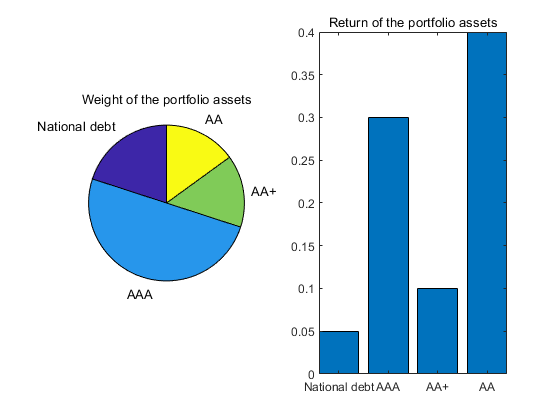


% Parameters of the asset portforlio
w_ip = [0.2, 0.5, 0.15, 0.15];
r_ip = [0.05, 0.3, 0.1, 0.4];

% Modified duration of the portfolio asset
MD_ip = [MD, MD_CB3A, MD_CB2APlus, MD_CB2A];

% Yields Change of the benchmark asset i, named as "delta_y_ib";
delta_y_ip = [0.1, 0.1, 0.1, 0.1];

% Remaining time ratio of the benchmark asset i, named as "delta_y_ib"
delta_m_ip = [0.9, 0.9, 0.9, 0.9];

figure;
labels = {'National debt','AAA','AA+','AA'};
subplot(1,2,1),pie(w_ip,labels),title('Weight of the portfolio assets');
subplot(1,2,2),bar(r_ip);title('Return of the portfolio assets');set(gca,'XTicklabel',labels);axis tight;


% Income return of the asset portforlio
IR = sum(w_ip.*r_ip.*delta_m_ib) ;

% Duration management returns:
DMR = sum( w_ip.*(-MD_ip) - w_ib.*(-MD_ib) ) ;

% Duration structure returns:
DSE = sum( w_ib.*(-MD_ib) .* (delta_y_ip- delta_y_ib) );

% Tresure return:
TreR = DMR + DSE;

% Bond portfolio return
BPR = sum( (w_ip.*(-MD_ip) - w_ib.*(-MD_ib)).*delta_y_ib );

% Single bond holding return
SBHR = sum( w_ib.*(-MD_ib).*(delta_y_ip - delta_y_ib) );

% Credit return
CR = BPR + SBHR;

% Excess return TR
TR = IR + TreR + CR; 


## 4.Result Plot

format shortG;
fprintf('Excess return, TR:    %-.4f\n',TR);

Excess return, TR:    0.1946


fprintf('(1)Income return, IR:    %-.4f\n',IR);

(1)Income return, IR:    0.2115


fprintf('(2)Tresure return, TreR:    %-.4f\n',TreR);

(2)Tresure return, TreR:    -0.0154


fprintf('----Duration management returns, DMR:    %-.4f\n',DMR);

----Duration management returns, DMR:    -0.0154


fprintf('----Duration structure returns, DSE:    %-.4f\n',DSE);

----Duration structure returns, DSE:    -0.0000


fprintf('(3)Credit return, CR:    %-.4f\n',CR);

(3)Credit return, CR:    -0.0015


fprintf('----Bond portfolio return, BPR:    %-.4f\n',BPR);

----Bond portfolio return, BPR:    -0.0015


fprintf('----Single bond holding return, SBHR:    %-.4f\n',SBHR);

----Single bond holding return, SBHR:    -0.0000



format shortG;
fprintf('超额回报, TR:    %.4f\n',TR);

超额回报, TR:    0.1946


fprintf('(1)收入回报, IR:    %.4f\n',IR);

(1)收入回报, IR:    0.2115


fprintf('(2)国债效应, TreR:    %.4f\n',TreR);

(2)国债效应, TreR:    -0.0154


fprintf('----久期管理收益, DMR:    %.4f\n',DMR);

----久期管理收益, DMR:    -0.0154


fprintf('----久期期限结构配置收益, DSE:    %.4f\n',DSE);

----久期期限结构配置收益, DSE:    -0.0000


fprintf('(3)利差效应, CR:    %.4f\n',CR);

(3)利差效应, CR:    -0.0015


fprintf('----券种配置收益, BPR:    %.4f\n',BPR);

----券种配置收益, BPR:    -0.0015


fprintf('----个券选择收益, SBHR:    %.4f\n',SBHR);

----个券选择收益, SBHR:    -0.0000


## 5.Function Called

function [P] = bondprice(C,F,y,k,m,N)
%The price of the bond is the discount of the cash flow.
% Inputs:
% C:    Interest
% F:    Final value of the bond
% y:    Yield to maturity
% k:    Number of interest payment per year
% N:    Total number of interest payment
%
% Outputs:
% P:    Market price of the bond;
% Created in 2020-12-21 by XuSUN.

P1 = C(:,end)/((1+y/k)^m);

P2 = zeros(1,N);

for n = 1:N
    P2(:,n) = C(:,n)./((1+y/k)^(n+m));
    P2 = sum(P2);
end

P3 = F/((1+y/k)^(N+m));
P = P1+P2+P3;

end

function [D] = bondduration(P,C,F,y,k,m,N)
%The price of the bond is the discount of the cash flow.
% Inputs:
% P:    Market price of the bond.
% C:    Interest.
% F:    Final value of the bond.
% y:    Yield to maturity.
% k:    Number of interest payment per year.
% N:    Total number of interest payment.
%
% Outputs:
% D:    Duration of the bond.

% Created in 2020-12-21 by XuSUN.

D1 = (m/k*C(:,end))/((1+y/k)^m);

D2 = zeros(1,N);

for n = 1:N
    D2(:,n) = ((m+n)/k)*C(:,n)./((1+y/k)^(n+m));
    D2 = sum(D2);
end

D3 = (m+N/k)*F/((1+y/k)^(N+m));
D = (D1+D2+D3)/P;

end

function [MD] = modifiedduration(D,y,k)
%The price of the bond is the discount of the cash flow.
% Inputs:
% D:    Duration of the bond.
% y:    Yield to maturity.
% k:    Number of interest payment per year.
%
% Outputs:
% MD:    Modified duration of the bond.

% Created in 2020-12-21 by XuSUN.
MD = D/(1+y/k);
end
